# Outer VRFT ?

Having tuned the inner controller we can move on to the next step: tuning the outer controller.

load 'quad_copter_models.mat';

OuterReferenceModel = mk_2nd_order(20, .7);
OuterReferenceModel_dt = c2d(OuterReferenceModel, Ts);

## VRFT Time

First we build the data. In the VRFT framework we calculate the reference signal that would need to be fed into the inner loop from the availble I/O data with:


$$r_i(t) = C^{-1}(z) \cdot u(t) + y_i(t) $$


and if we substitute $C$, $u$ and $y$ with our variables we have:


$$r_i(t) = R^{-1}_i(z) \cdot \delta M + \dot{q}$$


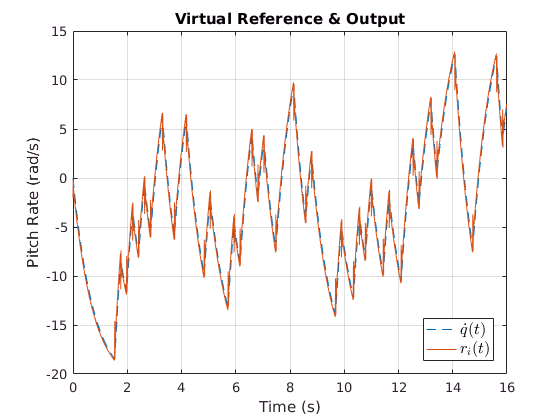

% I/O Signals
Ri_inv = OptimalInnerController^-1;

ei = lsim(Ri_inv, vrft_data.dM, vrft_data.time); 
ri = ei + vrft_data.q_dot;

figure()
    plot(vrft_data.time, vrft_data.q_dot, '--', vrft_data.time, ri);
    legend({'$$\dot{q}(t)$$', '$$r_i(t)$$'}, 'Location', 'SouthEast', 'Interpreter', 'latex', 'FontSize', 12);
    title('Virtual Reference & Output');
    xlabel('Time (s)'); ylabel('Pitch Rate (rad/s)');

The outer loop controls the pitch angle $\Theta$. This is not present in our data but we can get it by simply integrating the pitch rate ($\dot{q}$ - `q_dot`).

vrft_data.theta = lsim(integrator, vrft_data.q_dot, vrft_data.time);

We can now run the VRFT engine using the PD controller class.

[OptimalOuterController , Theta] = VRFT1_ry_theta(...
    ri, vrft_data.theta, OuterReferenceModel_dt,  PDControllerClass_dt, [], [], []);

fprintf('The optimal PID parametters for the inner controller are: \n');

The optimal PID parametters for the inner controller are: 


fprintf('Kp = %+7g, Original: %-7g\n', Theta(1), Ro.Kp);

Kp = +11.6233, Original: 1.61   


fprintf('Kd = %+7g, Original: %-7g\n', Theta(2), Ro.Kd);  

Kd = -0.0223586, Original: 0.00512


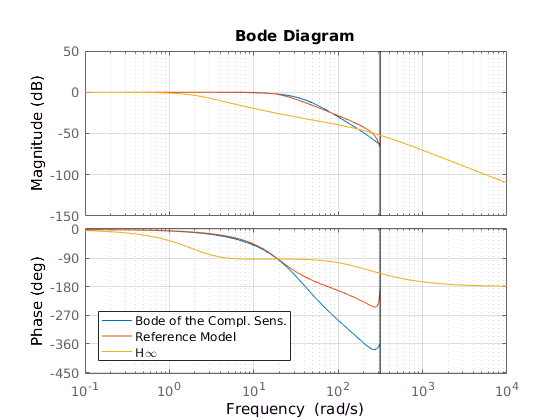



cloop = loopsens(integrator_dt * InnerLoop_VRFT, OptimalOuterController); 
OuterLoop_VRFT = cloop.Ti;

figure()
    bode(OuterLoop_VRFT, OuterReferenceModel_dt, OuterLoop_Hinf);
    legend('Bode of the Compl. Sens.', 'Reference Model', 'H\infty', 'location', 'SouthWest');
    grid on;

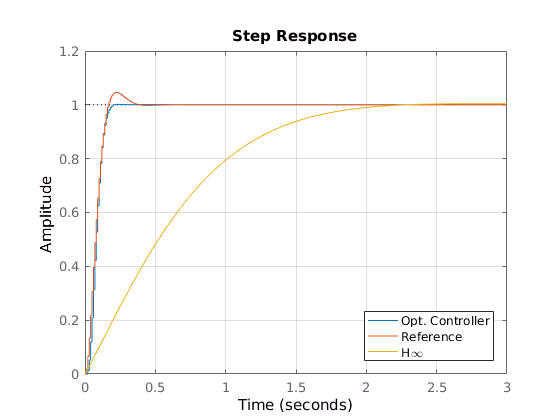

    
figure()
    step(OuterLoop_VRFT, OuterReferenceModel_dt, OuterLoop_Hinf);
    legend('Opt. Controller', 'Reference', 'H\infty', 'Location', 'southEast'); grid on;